# 1. App Classification Learner

Joan Manuel Ramos Refusta + Borja Cantero Aranda

fishertable = readtable('fisheriris.csv');
view(trainedModel.ClassificationTree,'Mode','graph');

yfit = trainedModel.predictFcn(fishertable);



## 2. Classificació automàtica d’espècies arbòries

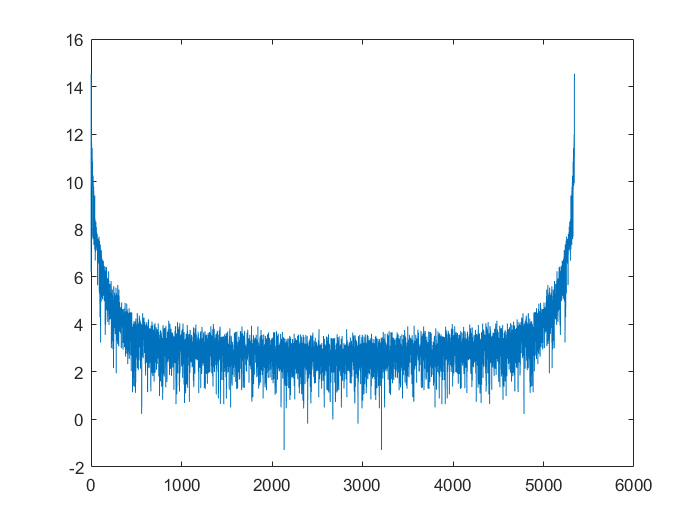

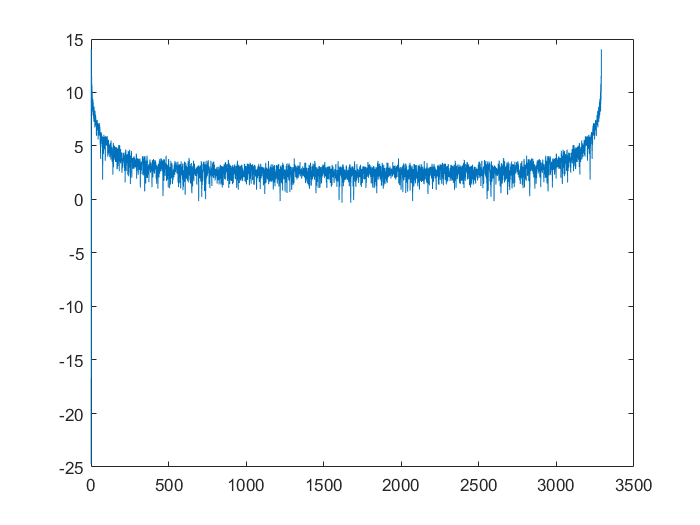

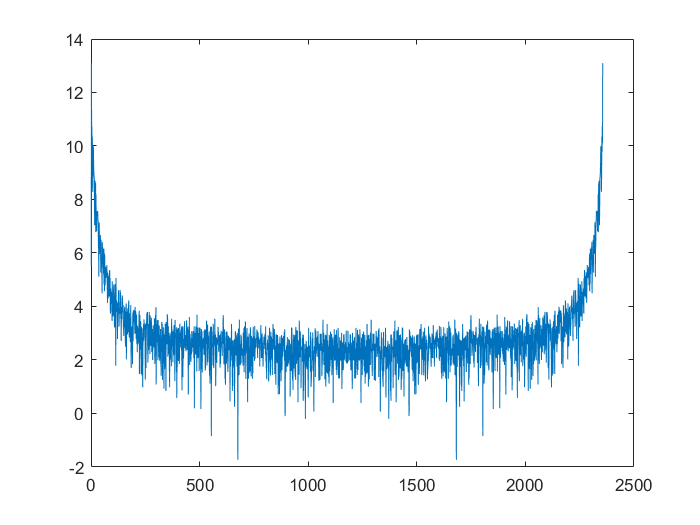

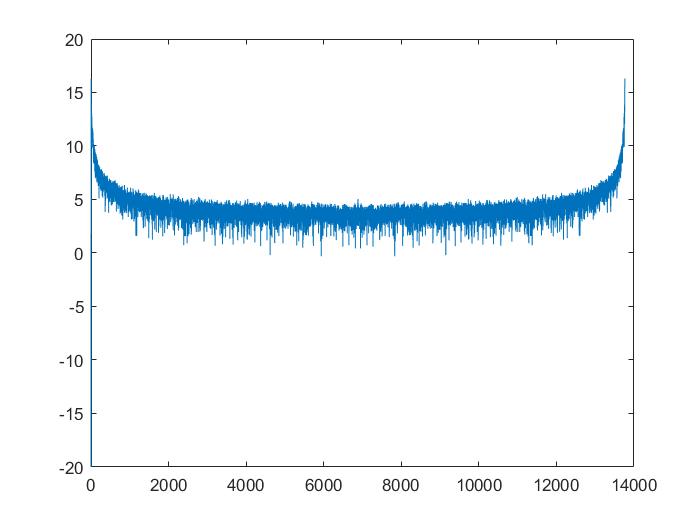

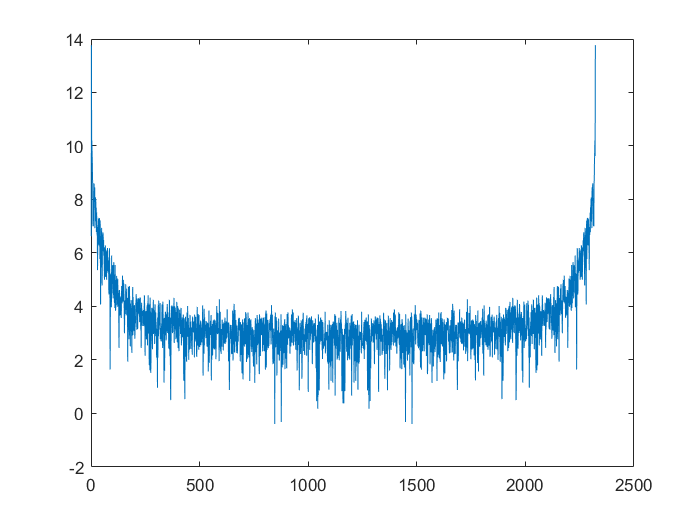

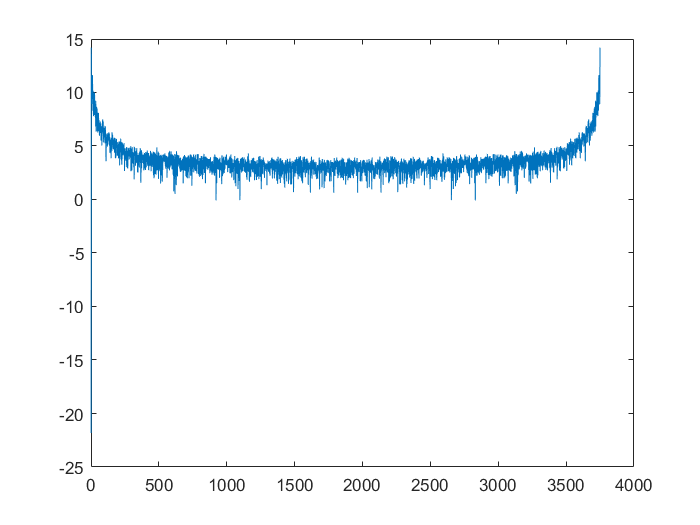

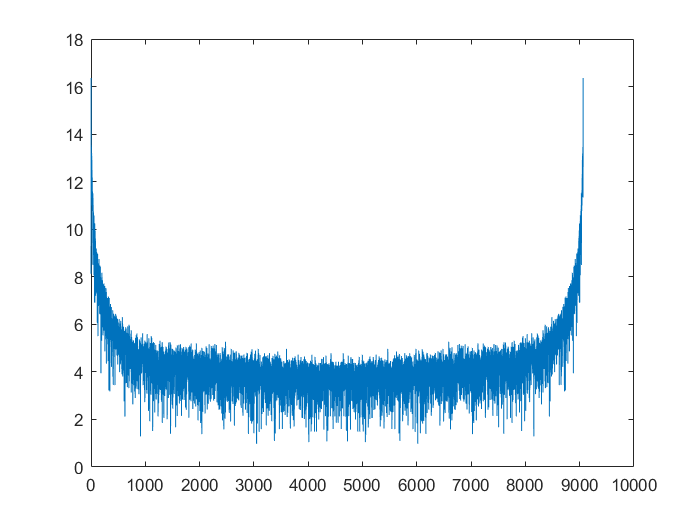

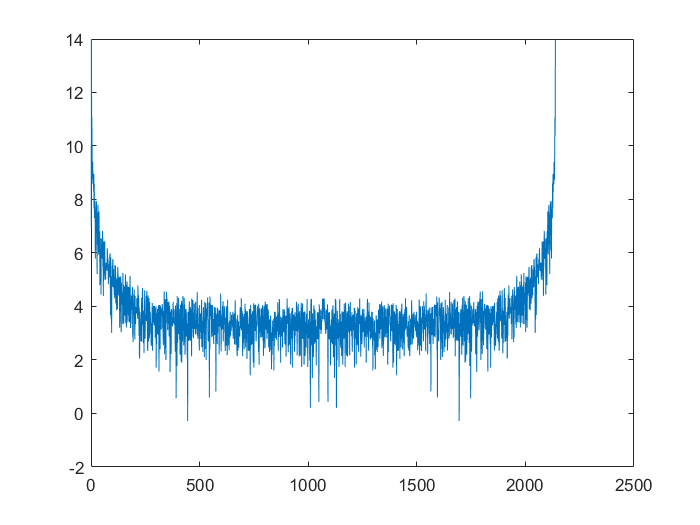

T = table('Size',[48 2],'VariableTypes',{'double','string'});

for i = 1:16
    k = string(i);
    ime = imread('Erable\' + k + '.jpg');
    imf = imread('Faig\' + k + '.jpg');
    imr = imread('Roure\' + k + '.jpg');
    
    bw = imcomplement(im2bw(ime));
    
    ee = strel('disk', 5);
    bw = imclose(bw,ee);
    bw = imopen(bw,ee);
    ee = strel('disk', 1);
    ero=imerode(bw,ee);
    cont=xor(ero,bw);
    
    [fila col] = find(bw,1); % Busquem el primer píxel
    B = bwtraceboundary(bw,[fila col],'E'); %direccio est a l'atzar
    
    mig=mean(B);
    B(:,1)=B(:,1)-mig(1);
    B(:,2)=B(:,2)-mig(2);
    % Convertim les coordenades a complexes
    s= B(:,1) + i*B(:,2);
    % Cal que la dimensio del vector sigui parell
    [mida bobo]=size(B);
    if(mida/2~=round(mida/2))
    s(end+1,:)=s(end,:); %dupliquem l'ultim
    mida=mida+1;
    end
    % Calculem la Fast Fourier Transform
    z=fft(s);
    % representem l’espectre
    figure,plot(log(abs(z)));
    %T(i,1).Var1 = s;
    T(i,2).Var2 = 'Erable';
    
    
    bw = imcomplement(im2bw(imf));
    
    ee = strel('disk', 5);
    bw = imclose(bw,ee);
    bw = imopen(bw,ee);

    ee = strel('disk', 1);
    ero=imerode(bw,ee);
    cont=xor(ero,bw);
    
    [fila col] = find(bw,1); % Busquem el primer píxel
    B = bwtraceboundary(bw,[fila col],'E'); %direccio est a l'atzar
    
    mig=mean(B);
    B(:,1)=B(:,1)-mig(1);
    B(:,2)=B(:,2)-mig(2);
    % Convertim les coordenades a complexes
    s= B(:,1) + i*B(:,2);
    % Cal que la dimensio del vector sigui parell
    [mida bobo]=size(B);
    if(mida/2~=round(mida/2))
    s(end+1,:)=s(end,:); %dupliquem l'ultim
    mida=mida+1;
    end
    % Calculem la Fast Fourier Transform
    z=fft(s);
    % representem l’espectre
    figure,plot(log(abs(z)));
    %T(i,1).Var1 = s;
    T(i+16,2).Var2 = 'Faig';
    
    
    bw = imcomplement(im2bw(imr));
    
    ee = strel('disk', 5);
    bw = imclose(bw,ee);
    bw = imopen(bw,ee);

    ee = strel('disk', 1);
    ero=imerode(bw,ee);
    cont=xor(ero,bw);

    
    [fila col] = find(bw,1); % Busquem el primer píxel
    B = bwtraceboundary(bw,[fila col],'E'); %direccio est a l'atzar
    
    mig=mean(B);
    B(:,1)=B(:,1)-mig(1);
    B(:,2)=B(:,2)-mig(2);
    % Convertim les coordenades a complexes
    s= B(:,1) + i*B(:,2);
    % Cal que la dimensio del vector sigui parell
    [mida bobo]=size(B);
    if(mida/2~=round(mida/2))
    s(end+1,:)=s(end,:); %dupliquem l'ultim
    mida=mida+1;
    end
    % Calculem la Fast Fourier Transform
    z=fft(s);
    % representem l’espectre
    figure,plot(log(abs(z)));
    %T(i+32,1).Var1 = s;
    T(i+32,2).Var2 = 'Roure';
end